# 波形の合成について

 　波形の切り出しに関して以下の三種類の検証を行った。

- 振幅方向の合成

- 時間軸方向の合成

## 1. テストデータ出の検証

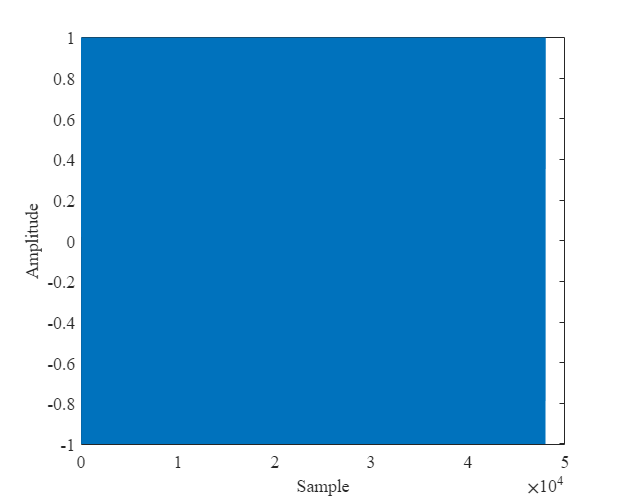

clear all

%% test 波形の作成
%パラメータ
Fs = 48e3;
f = 1000;
period = 1000;
% コンストラクタ
gen = CreateSignal(Fs,f,1);
vis = Visual(Fs,f);

%余弦波の作成
signal = gen.createCosSample(period);
signalDist = gen.createDistorionSignal(-6,-80,11,signal);
signalDist = signalDist.';

figure(100)
vis.plotSignal(signalDist);

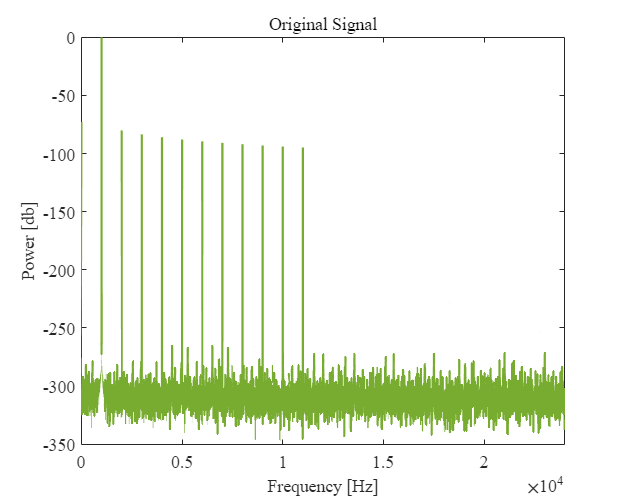

figure(2)
vis.plotFFT(signalDist(1:end-1),"ORIGIN",Fs/2)

%% インスタンス化
sep = Separation(Fs,f);
rec = Reconstruct(100);

### 1.1 時間軸方向への反転

    波形のピークを求めて切り出し点を決める。簡単にいうとピークピッキングを隣接サンプル間の差分から求めている。

   　-  Sepration.separateMotionを使用

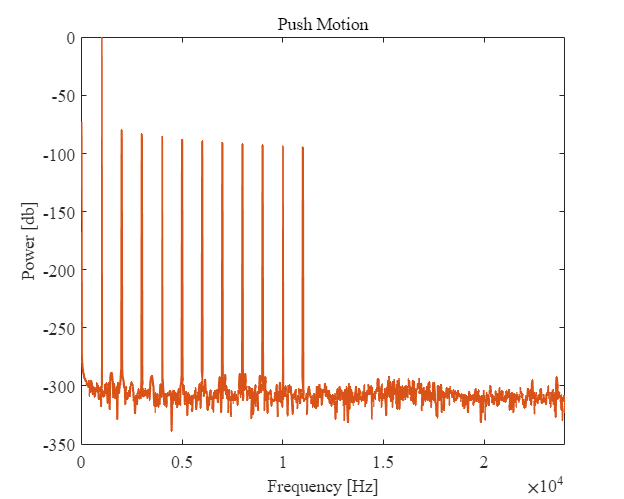

%% PUSH の合成
% 分離
pushCell = sep.separateExtendMotion(signalDist,1);
% 合成
pushHorizontalSignal = rec.reconstructHorizontal(pushCell,1);
vis.plotFFT(pushHorizontalSignal,"PUSH",Fs/2)

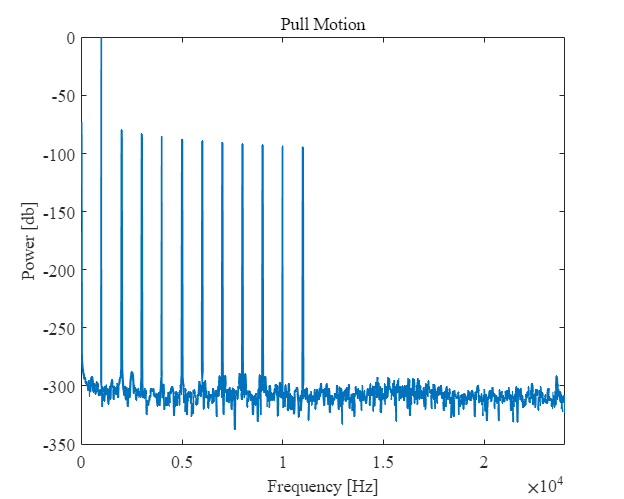

%% PULL の合成
% 分離
puLLCell = sep.separateExtendMotion(signalDist,2);
% 合成
pullHorizontalSignal = rec.reconstructHorizontal(pushCell,2);
vis.plotFFT(pullHorizontalSignal,"PULL",Fs/2)

### 1.2 振幅方向への反転

　振幅方向に各区間を反転させ、合成を行う

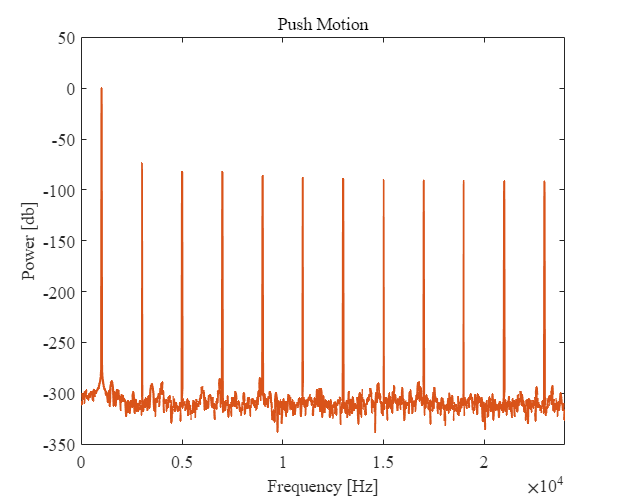

%% PUSH の合成
% 分離
pushCell = sep.separateExtendMotion(signalDist,1);
% 合成
pushHorizontalSignal = rec.reconstructVertical(pushCell,1);
vis.plotFFT(pushHorizontalSignal,"PUSH",Fs/2)

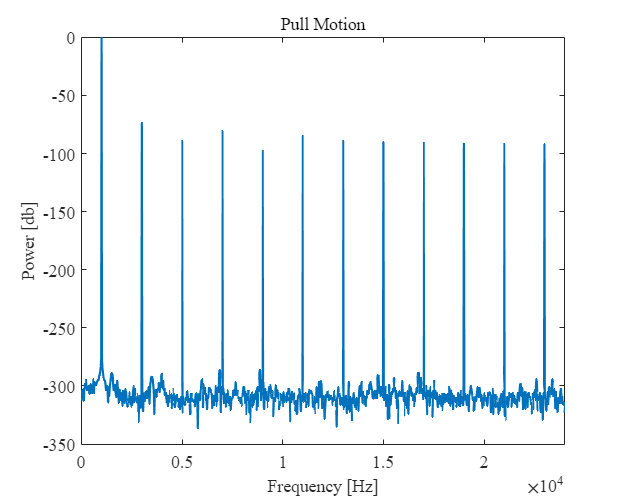

%% PULL の合成
% 分離
pushCell = sep.separateExtendMotion(signalDist,2);
% 合成
pushHorizontalSignal = rec.reconstructVertical(pushCell,2);
vis.plotFFT(pushHorizontalSignal,"PULL",Fs/2)

### 2. 実測波形出での検証

実測の波形に対して、前処理を行い、波形分離・合成を行う。

%% 読み込み
signalStruct = load("./notebook/testsignal/testSignal_1000.mat");
signal = signalStruct.signal;

%% 前処理
pre = Preprocess(Fs,f);
%trim silence
signal_p1 = pre.trimSilence(signal);
% upsample
signal_p2 = pre.resampleSignal(10*Fs,signal_p1);
Fs = 10*Fs;
% trim start end
trimPeriod = round(length(signal_p1)*0.05 / (Fs/f));
signal_p3 = pre.reshapeSignal(trimPeriod,signal_p2);
vis.plotSignal(signalDist);

### 2.1 時間軸方向への反転

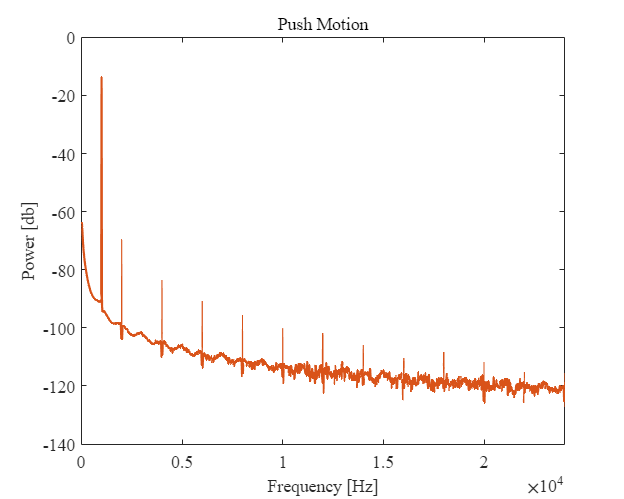

%% PUSH の合成
% 分離
sep = Separation(Fs,f);
pushCell = sep.separateExtendMotion(signal_p3,1);
% 合成
pushHorizontalSignal = rec.reconstructHorizontal(pushCell,1);
% plot
vis = Visual(Fs,f);
vis.plotFFT(pushHorizontalSignal,"PUSH",Fs/20)